%f = 40
f = 1500

f = 1500

w = 2 * pi * f;
T = 1/f;

exp(1i * pi / 4)

ans = 0.7071 + 0.7071i


point_distance = 0.01; %in m

c = 343.3 %in m/s

c = 343.3000

loss_per_distance = -3 % in dB

loss_per_distance = -3


lambda = c / f % in m

lambda = 0.2289


k = 2 * pi / lambda

k = 27.4535


N_hor = 600;
N_ver = N_hor;

No_linearray_elements = 6

No_linearray_elements = 6

points_per_element = N_ver / No_linearray_elements;

t_start = 0

t_start = 0

t_end = 0.403

t_end = 0.4030

d_t = (t_end - t_start) / No_linearray_elements;

pressure_field = zeros(N_hor, N_ver);
delay_times = zeros(N_ver, 1);

for i = 1:1:N_ver
    %delay_times(i) = t_start + round(i/points_per_element) * d_t;
    delay_times(i) = t_start + i * d_t;
end
delay_times

delay_times =     0.0672
    0.1343
    0.2015
    0.2687
    0.3358
    0.4030
    0.4702
    0.5373
    0.6045
    0.6717


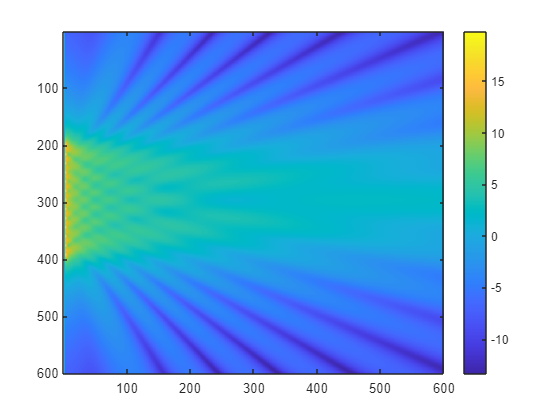

for y = 1:1:N_ver
    for x = 2:1:N_hor
        amplitude = 0;
        pressure = 0;
        for source = 200:16:400
            delta_x = x - 1;
            delta_y = y - source;
            distance = sqrt(delta_x^2 + delta_y^2) * point_distance;
            time = delay_times(source,1);
            pressure = pressure + exp(1i * (w * time - distance * k)) / distance;
        end
        pressure_field(y,x) = 10 * log10(abs(pressure));
    end
end


imagesc(pressure_field)
colorbar


%imagesc(spl_field)
%colorbar